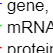



% 1) Define promoter strengths
k1_values = struct('J23100', 1.00, ...
                   'J23101', 0.70, ...
                   'J23106', 0.47, ...
                   'J23116', 0.16, ...
                   'J23117', 0.06);

% 2) Parameters (with placeholder k1, replaced in loop)
params.d1 = log(2)/3;
params.k2 = 8.23;
params.d2 = 0.02;
% k1 will be set in the loop

% 3) Initial state: [gene, mRNA, protein]
initialState = [17, 0, 0];

% 4) Time points
tspan = 0:0.1:180;  % from 0 to 180 in increments of 0.1

% 5) Prepare storage arrays (we'll store everything in a table-like cell array)
promoters = fieldnames(k1_values);

allResults = [];  % We will accumulate: [time, gene, mRNA, protein, k1Index] 
                  % then we can separate or plot

for i = 1:length(promoters)
    promoterName = promoters{i};
    k1_val = k1_values.(promoterName);
    
    % Update k1 in params
    params.k1 = k1_val;

    % 6) Solve using ode45
    % ODE system as a nested function or separate file
    [T, Y] = ode45(@(t, y) derivative(t, y, params), tspan, initialState);
    
    % Y has columns: [gene, mRNA, protein]
    
    % We'll create a matrix with T, Y, and a column for the promoter index
    promoterIdx = i * ones(size(T));  % or store the name if you prefer
    tempData = [T, Y, promoterIdx];
    
    % Accumulate
    allResults = [allResults; tempData];
end

% allResults columns: [time, gene, mRNA, protein, promoterIndex]

% 7) For plotting, we’ll do a multi-line log-scale plot.
figure; hold on;

% We'll assign different line styles for each promoter
lineStyles = {'-', '--', '-.', ':', '-'};  % example set, expand as needed

% We can define color map for components (gene, mRNA, protein)
colors = [0 0 1;   % gene in blue
          0 1 0;   % mRNA in green
          1 0 0];  % protein in red

legendEntries = {};  % Keep track for the legend

for i = 1:length(promoters)
    % Extract data for the i-th promoter
    rows = (allResults(:,5) == i);
    promoterData = allResults(rows,:);
    T = promoterData(:,1);
    gene   = promoterData(:,2);
    mRNA   = promoterData(:,3);
    protein= promoterData(:,4);
    
    % Plot each component
    % gene
    p1 = plot(T, gene, 'LineStyle', lineStyles{i}, 'Color', colors(1,:));
    legendEntries{end+1} = sprintf('gene, %s', promoters{i});
    hold on;
    
    % mRNA
    p2 = plot(T, mRNA, 'LineStyle', lineStyles{i}, 'Color', colors(2,:));
    legendEntries{end+1} = sprintf('mRNA, %s', promoters{i});
    
    % protein
    p3 = plot(T, protein, 'LineStyle', lineStyles{i}, 'Color', colors(3,:));
    legendEntries{end+1} = sprintf('protein, %s', promoters{i});
end

set(gca,'YScale','log');
xlabel('Time (min)');
ylabel('Concentration (log scale)');
title('Gene Expression Over Time for Different Promoter Strength');
legend(legendEntries, 'Location', 'best');
grid on;



% --- Nested function for ODE derivatives

function dydt = derivative(t, y, params)
    % y = [gene, mRNA, protein]
    gene = y(1);
    mRNA = y(2);
    protein = y(3);
    
    k1 = params.k1;
    d1 = params.d1;
    k2 = params.k2;
    d2 = params.d2;
    
    dGene = 0;
    dmRNA = k1 * gene - d1 * mRNA;
    dProtein = k2 * mRNA - d2 * protein;
    
    dydt = [dGene; dmRNA; dProtein];
end